% --- PUNTOS DE LA REGRESION ---
x = [0 1 3 4 2];
y = [0 2 2 5 4];

% --- PARAMETROS INICIALES ---
w = -1;
b = 0;
w_init = w;
b_init = b;

% --- PARAMETROS DEL ALGORITMO ---
epocas = 40;
nu = 0.005;

% --- CONFIGURACIÓN DE FUENTE ---
fuente = 'Times New Roman'; 

% Pre-asignamos vectores
loss_history = nan(1, epocas);
w_history = nan(1, epocas);
b_history = nan(1, epocas);

% --- INICIALIZACION DE LA FIGURA ---
figure(1);
set(gcf, 'Position', [100, 100, 1100, 600], 'Color', 'w');
filename = 'regresion_final_serif.gif'; 

x_limits = [-1 5];
y_limits = [-1 6];

% === CONFIGURACIÓN GLOBAL (CAMBIO CLAVE AQUÍ) ===

% Usamos \bf para iniciar negrita y \rm para volver a normal
% Eliminamos la propiedad 'FontWeight', 'bold' del sgtitle para que no afecte a todo
txt_titulo = sprintf('\\bfEntrenamiento Regresión Lineal\\rm\n w_0 = %.1f | b_0 = %.1f | \\nu = %.3f | Épocas: %d', ...
                     w_init, b_init, nu, epocas);

% Nota: No ponemos 'FontWeight', 'bold' aquí, dejamos que el TeX maneje el estilo
sgtitle(txt_titulo, 'FontSize', 15, 'FontName', fuente); 

% === SUBPLOT 1: REGRESIÓN (IZQUIERDA) ===
ax1 = subplot(1, 2, 1);
pos1 = get(ax1, 'Position'); 
pos1(4) = pos1(4) * 0.85;    
set(ax1, 'Position', pos1);
set(ax1, 'FontName', fuente, 'FontSize', 12); 

hold on;
plot(x, y, 'ko', 'MarkerSize', 8, 'MarkerFaceColor', 'k', 'DisplayName', 'Datos'); 
x_line = linspace(x_limits(1), x_limits(2), 100);
h_model = plot(x_line, w*x_line+b, 'b-', 'LineWidth', 2, 'DisplayName', 'Modelo'); 
grid on;
axis([x_limits y_limits]);

xlabel('x', 'FontName', fuente); 
ylabel('y', 'FontName', fuente);
legend('Location', 'northwest', 'FontName', fuente);

% Forzamos FontWeight normal, porque MATLAB pone los títulos en negrita por defecto
h_title1 = title('Iniciando...', 'FontName', fuente, 'FontWeight', 'normal'); 
hold off;

% === SUBPLOT 2: HISTORIAL (DERECHA) ===
ax2 = subplot(1, 2, 2);
pos2 = get(ax2, 'Position'); 
pos2(4) = pos2(4) * 0.85;    
set(ax2, 'Position', pos2);
set(ax2, 'FontName', fuente, 'FontSize', 12);

hold on;
h_loss = plot(1, 0, 'r', 'LineWidth', 2, 'MarkerSize', 4, 'DisplayName', 'Loss');
h_w    = plot(1, 0, 'g', 'LineWidth', 2, 'MarkerSize', 4, 'DisplayName', 'w');
h_b = plot(1, 0, 'm', 'LineWidth', 2, 'MarkerSize', 4, 'DisplayName', 'b');
grid on;
xlim([1 epocas]);
ylim([-2 10]); 

xlabel('Época', 'FontName', fuente);
% Forzamos FontWeight normal aquí también
h_title2 = title('Dinámica', 'FontName', fuente, 'FontWeight', 'normal'); 
legend('Location', 'northeast', 'FontName', fuente);
hold off;

drawnow; 

% --- BUCLE DE ENTRENAMIENTO ---
disp('Iniciando entrenamiento...');

Iniciando entrenamiento...


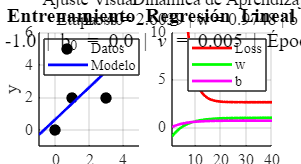

Etapa 5 | Loss 19.4176
Etapa 10 | Loss 5.2928
Etapa 15 | Loss 3.0350
Etapa 20 | Loss 2.6738
Etapa 25 | Loss 2.6158
Etapa 30 | Loss 2.6062
Etapa 35 | Loss 2.6044
Etapa 40 | Loss 2.6039


for epoca = 1:epocas
    % 1. Cálculo
    y_hat = w.*x + b;
    current_loss = sum((y_hat - y).^2)/2;
    
    % 2. Guardar datos
    loss_history(epoca) = current_loss;
    w_history(epoca) = w;
    b_history(epoca) = b;

    if mod(epoca, 5) == 0
        fprintf('Etapa %d | Loss %.4f\n', epoca, current_loss);
    end
    
    % --- ACTUALIZACIÓN VISUAL ---
    
    % Izquierda
    set(h_model, 'YData', w * x_line + b);
    set(h_title1, 'String', sprintf('Ajuste Visual\nEtapa: %d', epoca));
    
    % Derecha
    iter = 1:epoca;
    set(h_loss, 'XData', iter, 'YData', loss_history(1:epoca));
    set(h_w,    'XData', iter, 'YData', w_history(1:epoca));
    set(h_b,    'XData', iter, 'YData', b_history(1:epoca));
    
    % Zoom dinámico
    if current_loss > 9 && epoca < 10
         ylim([-2 current_loss+2]);
    else
         ylim([-2 10]); 
    end
    
    set(h_title2, 'String', sprintf('Dinámica de Aprendizaje\n Loss = %.4f | w = %.4f | b = %.4f', current_loss, w, b));
    
    drawnow;
    
    % --- GIF ---
    frame = getframe(gcf); 
    im = frame2im(frame); 
    [imind, cm] = rgb2ind(im, 256); 
    
    if epoca == epocas; delay = 3.0; else; delay = 0.2; end

    if epoca == 1 
        imwrite(imind, cm, filename, 'gif', 'Loopcount', inf, 'DelayTime', delay); 
    else 
        imwrite(imind, cm, filename, 'gif', 'WriteMode', 'append', 'DelayTime', delay); 
    end

    % --- UPDATE GRADIENT ---
    w = w - nu * x * (y_hat - y)';
    b = b - nu * sum(y_hat - y);
end


disp(['GIF guardado como: ', filename]);

GIF guardado como: regresion_final_serif.gif
